clc; clear; close all
format compact

w1 = [2 6];
w2 = [9 11]; % Omit 12 and 13
w3 = [16 20];

h = [7 17]

h =      7    17


hours = h(2) - h(1)

hours = 10


w1_days = w1(2) - w1(1) + 1;
w2_days = w2(2) - w2(1) + 1;
w3_days = w3(2) - w3(1) + 1;

w1_hours = w1_days * hours;
w2_hours = w2_days * hours;
w3_hours = w3_days * hours;

data = load('activations/activations_all_corrected.csv')

data =     10    30    11    27    35
    10    30    11    28    34
    10    30    11    32    17
    10    30    11    33    18
    10    30    11    37     4
    10    30    11    37    33
    10    30    11    40     8
    10    30    11    40    15
    10    30    11    41    30
    10    30    11    43    48



% Activations per hour
data_w1_days = zeros(w1_days, 1);
data_w1_hours = zeros(w1_hours, 1);
for i = w1(1):w1(2)
    for ii = h(1):h(2)-1
        idxs = data(:, 2) == i & data(:, 3) == ii;
        data_w1_hours((i - w1(1)) * hours + ii - h(1) + 1) = sum(idxs);
    end
    idxs = data(:, 2) == i;
    data_w1_days(i - w1(1) + 1) = sum(idxs);
end
data_w1_days

data_w1_days =    345
   352
   365
   338
   397


data_w1_hours

data_w1_hours =     37
    63
    27
    38
    43
    53
    18
    12
    27
    11



data_w2_days = zeros(w2_days, 1);
data_w2_hours = zeros(w2_hours, 1);
for i = w2(1):w2(2)
    for ii = h(1):h(2)-1
        idxs = data(:, 2) == i & data(:, 3) == ii;
        data_w2_hours((i - w2(1)) * hours + ii - h(1) + 1) = sum(idxs);
    end
    idxs = data(:, 2) == i;
    data_w2_days(i - w2(1) + 1) = sum(idxs);
end
data_w2_days

data_w2_days =    419
   334
   346


data_w2_hours

data_w2_hours =     41
    83
    29
    42
    55
    45
    27
    30
    36
    17



data_w3_days = zeros(w3_days, 1);
data_w3_hours = zeros(w3_hours, 1);
for i = w3(1):w3(2)
    for ii = h(1):h(2)-1
        idxs = data(:, 2) == i & data(:, 3) == ii;
        data_w3_hours((i - w3(1)) * hours + ii - h(1) + 1) = sum(idxs);
    end
    idxs = data(:, 2) == i;
    data_w3_days(i - w3(1) + 1) = sum(idxs);
end
data_w3_days

data_w3_days =    468
   585
   537
   426
   410


data_w3_hours

data_w3_hours =     47
    94
    28
    40
    64
    73
    29
    33
    28
    11



% Total number of activations each weak
n_w1 = sum(data_w1_hours);
n_w2 = sum(data_w2_hours);
n_w3 = sum(data_w3_hours);

% Mean activations per day
mu_w1_days = mean(data_w1_days)

mu_w1_days = 359.4000

mu_w2_days = mean(data_w2_days)

mu_w2_days = 366.3333

mu_w3_days = mean(data_w3_days)

mu_w3_days = 485.2000


% Standard deviation per day
std_w1_days = std(data_w1_days)

std_w1_days = 23.2659

std_w2_days = std(data_w2_days)

std_w2_days = 46.0036

std_w3_days = std(data_w3_days)

std_w3_days = 74.3283


% Mean activations per hour
mu_w1_hours = mean(data_w1_hours)

mu_w1_hours = 34.6000

mu_w2_hours = mean(data_w2_hours)

mu_w2_hours = 33.2667

mu_w3_hours = mean(data_w3_hours)

mu_w3_hours = 47.0400


% Standard deviation per hour
std_w1_hours = std(data_w1_hours)

std_w1_hours = 22.9783

std_w2_hours = std(data_w2_hours)

std_w2_hours = 17.8884

std_w3_hours = std(data_w3_hours)

std_w3_hours = 40.4288

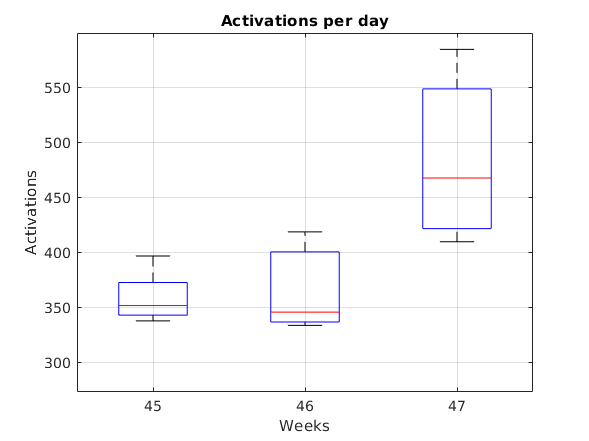


% Boxplot days
group = [
    1 * ones(size(data_w1_days))
    2 * ones(size(data_w2_days))
    3 * ones(size(data_w3_days))
];
boxplot([data_w1_days; data_w2_days; data_w3_days], group, "Labels", {45, 46, 47})
grid on
title("Activations per day")
xlabel("Weeks")
ylabel("Activations")

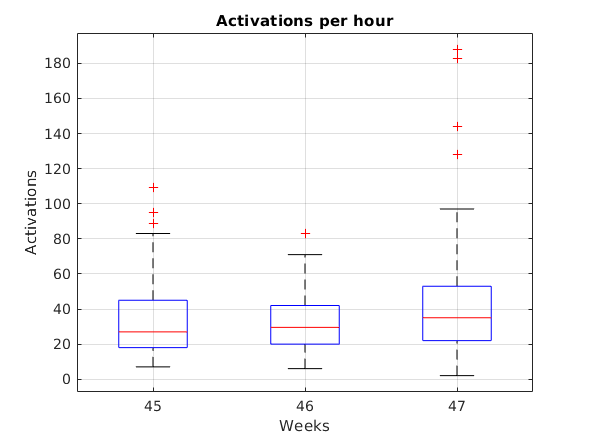


% Boxplot hours
group = [
    1 * ones(size(data_w1_hours))
    2 * ones(size(data_w2_hours))
    3 * ones(size(data_w3_hours))
];
boxplot([data_w1_hours; data_w2_hours; data_w3_hours], group, "Labels", {45, 46, 47})
grid on
title("Activations per hour")
xlabel("Weeks")
ylabel("Activations")


% Days
% Hypothesis tests
disp("Hypothesis 1: People will use the hand-sanitising foam dispenser differently depending on the visual stimuli that accompanies it.")

Hypothesis 1: People will use the hand-sanitising foam dispenser differently depending on the visual stimuli that accompanies it.


disp("W1 not equal to W2")

W1 not equal to W2


[p, h] = ranksum(data_w1_days, data_w2_days)

p = 1

h = logical
   0

disp("W1 not equal to W3")

W1 not equal to W3


[p, h] = ranksum(data_w1_days, data_w3_days)

p = 0.0079

h = logical
   1


disp("Hypothesis 2: People will use the hand-sanitising foam dispenser more frequently when it is accompanied by interesting visual stimuli.")

Hypothesis 2: People will use the hand-sanitising foam dispenser more frequently when it is accompanied by interesting visual stimuli.


disp("W1 smaller than W3")

W1 smaller than W3


[p, h] = ranksum(data_w1_days, data_w3_days, "Tail", "left")

p = 0.0040

h = logical
   1

disp("W2 smaller than W3")

W2 smaller than W3


[p, h] = ranksum(data_w2_days, data_w3_days, "Tail", "left")

p = 0.0357

h = logical
   1


% Hours
% Hypothesis tests
disp("Hypothesis 1: People will use the hand-sanitising foam dispenser differently depending on the visual stimuli that accompanies it.")

Hypothesis 1: People will use the hand-sanitising foam dispenser differently depending on the visual stimuli that accompanies it.


disp("W1 not equal to W2")

W1 not equal to W2


[p, h] = ranksum(data_w1_hours, data_w2_hours)

p = 0.8580

h = logical
   0

disp("W1 not equal to W3")

W1 not equal to W3


[p, h] = ranksum(data_w1_hours, data_w3_hours)

p = 0.1373

h = logical
   0


disp("Hypothesis 2: People will use the hand-sanitising foam dispenser more frequently when it is accompanied by interesting visual stimuli.")

Hypothesis 2: People will use the hand-sanitising foam dispenser more frequently when it is accompanied by interesting visual stimuli.


disp("W1 smaller than W3")

W1 smaller than W3


[p, h] = ranksum(data_w1_hours, data_w3_hours, "Tail", "left")

p = 0.0686

h = logical
   0

disp("W2 smaller than W3")

W2 smaller than W3


[p, h] = ranksum(data_w2_hours, data_w3_hours, "Tail", "left")

p = 0.1204

h = logical
   0

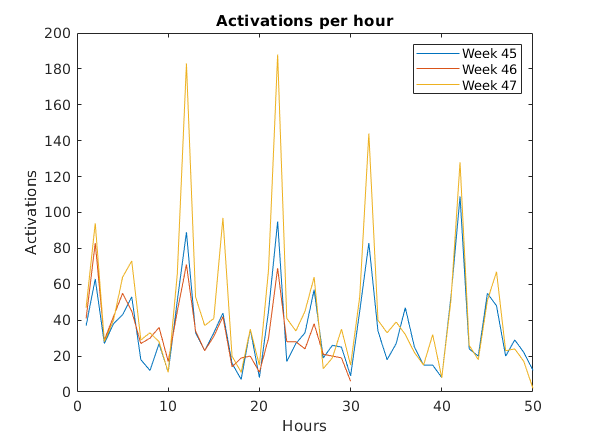


% Days
plot(data_w1_hours)
hold on
plot(data_w2_hours)
plot(data_w3_hours)
legend(["Week 45", "Week 46", "Week 47"])
title("Activations per hour")
xlabel("Hours")
ylabel("Activations")
hold off